# Population analyses: Bayesian decoding, PCA and ICA

Population analyses is a pivotal framework in neuroscience that enable us to identify and characterize underlying patterns within complex neural ensembles. In the context of our data on hippocampal place cell activity, three prominent techniques stand out: Bayesian decoding, Principal Component Analysis (PCA), and Independent Component Analysis (ICA). 

This tutorial is divided into two parts, where the main objectives will be to:

- decode positions and directions of movement from the activity of hipoocampal neurons

- identify cell assemblies that tend to fire together using independent component analysis

## 2.1. Bayesian decoding from neural spike trains

In neuroscience, bayesian decoding often consists in estimating a probability density for one or more variables given a set of spike trains recorded from a neurolnal population. In the hippocampus, place cells fire when the animal is at specific location on the track. This selectivity corresponds to the encoding of spatial positions by hippocampal neurons. Conversely, estimating positions of the animal from ensembles of hippocampal neuronal corresponds to decoding of positions from neural activity. Bayesian decoding helps us unravel the neural code underlyng the encoding of stimuli at the population level. You can also think of it as the kind of operation that neurons downstream to your structure of interest would have to perform in order to infer some variable given the activity that they receive from their inputs.

In this turorial, we will use Bayesian decoding to reconstruct the animal's position and its direction of movement from the observed neural activity. This process involves applying Bayesian theorem to compute the posterior probability of the animal's position given the pattern of spikes observed across the population. This posterior probability is calculated from the likelihood of observing a given pattern of spikes given the position of the animal, and from the prior probability of the animal being in a certain place. This can be formalized as follows (see* Zhang, Ginzburg, McNaughton and Sejnowski, JNP, 1998*):

- **Bayes theorem**: 

                                                                
$$P\left(x_t \;|{\;\mathrm{spk}}_t \right)\times \;P\left({\;\mathrm{spk}}_t \right)=P\left({\;\mathrm{spk}}_t \;|\;x_t \right)\times P\left(x_t \right)$$


            where $x_t$ is the posiiton of the animal at time *t*, spk is the pattern of spike counts observed across the population at time t

- Assuming **independence** between neurons, we can estimate the likelihood $P\left({\;\mathrm{spk}}_t \;|\;x_t \right)$ as: 

                                                                            
$$P\left({\;\mathrm{spk}}_t \;|\;x_t \right)=\prod_i^N P\left({\mathrm{spk}}_{t,i} \;|\;x_t \right)$$


            where N is the number of cells.

- Assuming that spikes have a **Poisson distribution** (we don't have to but it's easier), the posterior can be expressed as:

                                                                 
$$P\left({\;\mathrm{spk}}_t \;|\;x_t \right)=\prod_i^N \frac{{\left(\tau \times f_i \left(x_t \right)\right)}^{{\mathrm{spk}}_{t,i} } }{{\mathrm{spk}}_{t,i} \;!}\times e^{\left(-\tau \;\times {\;f}_i \;\left(x_t \right)\right)}$$


            where $f_i \left(x_t \right)$ is the average firing rate of cell *i* at position $x_t$ and $\tau \;$ is the length of the decoding window over which spikes are counted in ${\mathrm{spk}}$.

The analyses described in this section can be run by calling the following set of functions:

%define parameters for decoding
decparams = DefineDecParams(Nav,Spk);

%change parameters here if necessary

%compute Bayesian decoding, 2D
Dec = DecodingAnalysis2D(Nav, Spk.spikeTrain, decparams);

%For 1D decoding, you may also start with the following simpler function
% Dec = DecodingAnalysis(Nav, Spk.spikeTrain, decparams);

*Some useful function that you will also find here are: ***ComputeBayesMAP2D.m**, 

### 3.1.1. Loading and preprocessing the behavioral and spiking data (as done in Tutorial1)

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = DefineLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

### 3.1.2 Parameters for estimating place fields

Defining a set of parameters needed for the decoder such as the bin size used for discretizing the X variable or the experiemental conditions over which place fields should be estimated (aka the training set of the decoder).

%Experimental condition over which the decoder will be trained
decparams.condition = [1 3 5];

%lap type over which the decoder will be trained
decparams.dir = [-1 1];

%lap types over which the decoder will be trained
decparams.laptype = [-1 0 1];

%Minimum speed threshold over which the decoder will be trained
decparams.spdthreshold = 2.5;

%Subset of cells used for decoding. By default we'll use only pyramidal
%cells since interneurons with high firing rates can strongly bias the
%decoder.
decparams.cellidx = Spk.PyrCell;

%Sampling rate of the data
decparams.sampleRate = 1 / nanmean(diff(Nav.sampleTimes));

%Range of positions (in cm) over which decoding will be performed, ie over
%which place fields will be computed
decparams.Xrange = [0 100];

%Size of the position bins (in cm).
decparams.Xbinsize = 4;

%Size of the gaussian window for smoothing place fields (in cm).
decparams.Xsmthbinsize = 2;

%Size of the gaussian window for smoothing place fields (in bins).
decparams.XsmthNbins = decparams.Xsmthbinsize / decparams.Xbinsize;

%Edges of position bins used to discretize positions
decparams.Xbinedges = decparams.Xrange(1):decparams.Xbinsize:decparams.Xrange(2);

%Occupancy threshold above which positions are included in the place field
%estimate
decparams.occ_th = 0;

%Minimal number of spikes over the train set to consider a cell for
%decoding
decparams.nspk_th = 0;

%Number of folds to consider for cross-validation on the train set
decparams.kfold = 10;

%Size of the decoding window in seconds
decparams.dectimewin = .30;

This set of parameters can be obtained by calling **DefineDecParams.m**

decparams = DefineDecParams(Nav,Spk);

### 3.1.3 Estimating the place fields that will be used to calculate the likelihood

We first estimate the place fields on a subset of the data. This subset of the data where place field were estimated ultimately represent the training set for the decoder: this is based on selectivity measured on these data that te decoder will infer the position of the animal on the entire dataset.

Since we want to decode position and direction of travel, we will estimate position x direction place fields, similar to what we have done in tutorial 2.1.

%Time indices over which place fields used for decoding will be estimated.
traintidx = ismember(Nav.Condition, decparams.condition) &...
    ismember(Nav.XDir, decparams.dir) &...
    Nav.Spd > decparams.spdthreshold &...
    ~isnan(Nav.X);

%Selecting cell indices over which to compute place fields
cellidx = find(decparams.cellidx & sum(Spk.spikeTrain(traintidx,:), 1) > decparams.nspk_th);
spikeTrain = Spk.spikeTrain(:,cellidx);

%no subsetting of Xpos and XDir for now
Xpos = Nav.Xpos;
Dir = Nav.XDir;

%number of cells selected for decoding
ncells = size(spikeTrain, 2);

%number of position bins
nXbins = numel(decparams.Xbinedges) - 1;

%number of direction bins
nLRbins = 2;
LRsmthNbins = 0;%no smoothing across directions

%Discretizing position vectors according to decparams.Xbinedges
Xpos_discrete = discretize(Xpos, decparams.Xbinedges);

%Discretizing XDir so that 2 corresponds to left to right (ie
%Nav.XDir = 1) and 1 corresponds to right to left (ie Nav.XDir = -1).
Dir_discrete = NaN(size(Dir));
Dir_discrete(Dir == 1) = 2;
Dir_discrete(Dir == -1) = 1;

%Subsetting Xpos_discrete, Dir_discrete and spikeTrain on the training set
Xpos_discrete_trainset = Xpos_discrete(traintidx);
Dir_discrete_trainset = Dir_discrete(traintidx);
spkTrain_trainset = spikeTrain(traintidx,:);

%Computing occupancy map (same for all cells) on the train set
flat = 1/decparams.sampleRate * ones(size(Xpos_discrete_trainset));
occmap = Compute2DMap(Dir_discrete_trainset, Xpos_discrete_trainset, flat, nLRbins, nXbins);

%Removing occupancy for position bins below the occupancy threshold
occmap(occmap <= decparams.occ_th) = NaN;

%Smoothing the occupancy map with a 2D gaussian window.
occmap = GaussianSmooth(occmap, [decparams.XsmthNbins LRsmthNbins]);

%Initilizing the spike count map
scmap = NaN(ncells, nXbins, nLRbins);

%Computing and smoothing the spike count map for each cell
for icell = 1:ncells
    scmap(icell,:,:) = Compute2DMap(Dir_discrete_trainset, Xpos_discrete_trainset, spkTrain_trainset(:,icell), nLRbins, nXbins);
    scmap(icell,isnan(occmap)) = NaN;
    scmap(icell,:,:) = GaussianSmooth(squeeze(scmap(icell,:,:)), [decparams.XsmthNbins LRsmthNbins]);
end

%Calculating the place field x direction maps by dividing scmap and occmap
occmap = permute(occmap, [3 1 2]);%permuting dimension for convenience
mapXY = scmap ./ occmap;

### 3.1.4 Decoding positions and directions

Now that we have computed the place fields, we can start doing some decoding.

%Smoothing the spike train over the decoding window to get spike counts
spkCount = zeros(size(spikeTrain));
decbinwin = 2 * floor(0.5 * decparams.dectimewin * decparams.sampleRate) + 1;%odd number of bins for smoothing
for icell = 1:size(spikeTrain,2)
    spkCount(:,icell) = smooth(spikeTrain(:,icell), decbinwin) * decbinwin;
end

%number of data points
ntimepts = size(spkCount, 1);

%Initializing decoded variables
XDecMax = NaN(ntimepts,1);%Maximum a posteriori (M.A.P.) for positions
YDecMax = NaN(ntimepts,1);%Maximum a posteriori (M.A.P.) for direction
XDecMean = NaN(ntimepts,1);%Position expectancy
YDecMean = NaN(ntimepts,1);%Direction expectancy

%We don't want to decode positions from the same set of data that has been
%used to compute the place fields, otherwise we would probably overfit
%substantially the data. So for now we can only decode positions on data
%sets that haven't been used for the training.
%Computing decoded positions for data points that are not included in the
%train set.
[YDecMax(~traintidx), XDecMax(~traintidx), YDecMean(~traintidx), XDecMean(~traintidx)] = ...
    ComputeBayesMAP2D(mapXY, spkCount(~traintidx,:), decparams.dectimewin);

Let's try to see a little closer how decoding is performed in ComputeBayesMAP2D.m.

We'll consider the following:

map =  mapXY;
spk = spkCount(~traintidx,:);
dectimewin = decparams.dectimewin;
mapprior = ones([1 size(map, [2 3])]);

Calculating the posterior probability distribution for all time bins, using the 4 variables above and the formula for computing the posterior probability given in the introduction.

%Permuting dimensions to get first dimension as a singleton and do some
%element-wise multiplication with spk more conveniently
map = permute(map, [4 1 2 3]);
mapprior = permute(mapprior, [4 1 2 3]);

%Computing the posterior probability P(X,Y | spk). We'll do it as a for
%loop over the number of cells to avoid memory issues.
ncells = size(spk, 2);
map = map + eps;%to avoid reaching precision limit

%Initializing the posterior with the terms independent of time,
% i.e. the prior probability and the exp of the sum of the place fields.
Posterior = mapprior .* exp(-dectimewin .* sum(map, 2));

%Looping across cells to multiply by the product of likelihoods.
for icell = 1:ncells
    Posterior = Posterior .* (map(1,icell,:,:) .^ spk(:,icell));
end

%We should end up with a matrix of probability of size ntimes x nXbins x
%nYbins
Posterior = squeeze(Posterior);

%Normalizing so to that the sum of probabilities over positions equals 1.
Posterior = Posterior ./ nansum(Posterior, [2 3]);

So we have the probability density function of positions and directions for each time bin. This is an arry of size ntimes x nXbins x nLRbins

We need to estimate a single decoded position for each time bin.

First estimate the maximum a posteriori solution, which is simply the bin where the posterior probability is the highest

%Taking the decoded position as the maximum of the posterior probability
%distribution (M.A.P. estimate)
[~, DecMax] = max(Posterior, [], [2 3], 'linear');

%Converting DecMax from linear indices to subscripts
[~,YMaxDec, XMaxDec] = ind2sub(size(Posterior), DecMax);

This is what is most generally used as an estimate of the decoded position.

But statistically speaking, we can also estimate the position as the expectancy of the distribution of posterior probabilities, i.e. taking the mean position weighted by the distribution.

%We'll compute the mean decoded position on the marginal of the posterior
%distribution along the considered variable.
%First for the Y variable (i.e. positions in our case)
YPosterior = squeeze(nansum(Posterior, 3)) / 2;
Ybins = (1:size(Posterior, 2))';
YPosterior(isnan(YPosterior)) = 0;
YMeanDec = (YPosterior * Ybins) ./ sum(YPosterior, 2);

%Then for the X variable (i.e. direction of travel for us)
XPosterior = squeeze(nansum(Posterior, 2)) / 2;
Xbins = (1:size(Posterior, 3))';
XPosterior(isnan(XPosterior)) = 0;
XMeanDec = (XPosterior * Xbins) ./ sum(XPosterior, 2);

Finally, and that's optional, we'll just ignore decoded positions if there were no spikes in a time bin.

%Ignoring decoded positions if no cell fired (not necessary, up to you)
mua = sum(spk, 2);
XMaxDec(mua == 0) = NaN;
YMaxDec(mua == 0) = NaN;
XMeanDec(mua == 0) = NaN;
YMeanDec(mua == 0) = NaN;

The code above can be run by calling **ComputeBayesMAP2D.m.**

Compare your results with the output of this function above

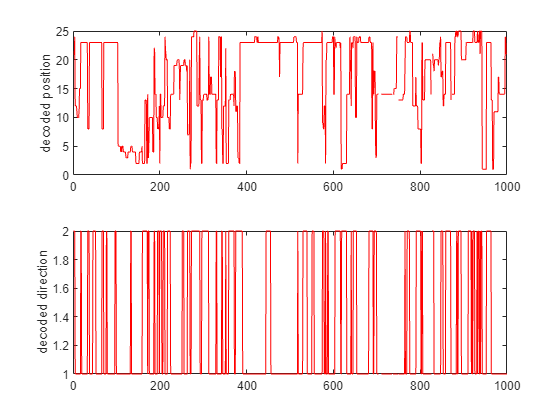

figure;

%plotting only a fraction of all indices
idx = find(~traintidx);
npts = min(numel(idx), 1000);

%checking MAP estimate of decoded position
subplot(2,1,1)
plot(XDecMax(idx(1:npts)),'k');
hold on;plot(YMaxDec(1:npts),'r');
ylabel('decoded position');

%checking MAP estimate of decoded direction
subplot(2,1,2)
idx = find(~traintidx);
plot(YDecMax(idx(1:npts)),'k');
hold on;plot(XMaxDec(1:npts),'r');
ylabel('decoded direction');

### 3.1.4 Cross-validated decoding 

So we've computed decoded positions and directions but only for time bins that were not in the train set. How can we decode positions and directions for the training set without overfitting? 

%Defining a partition of the data for k-fold cross-validation. NB: we
%should normally be more careful about the fact that the spike count data
%are actually smoothed over time...
ntimepts_trainset = sum(traintidx);
cv = crossvalPartition(ntimepts_trainset, decparams.kfold);

%Subsetting Xpos, Direction, spike train and spike count on the train set.
Xpos_discrete_trainset = Xpos_discrete(traintidx);
Dir_discrete_trainset = Dir_discrete(traintidx);
spkTrain_trainset = spikeTrain(traintidx,:);
spkCount_trainset = spkCount(traintidx,:);

%Initializing the place fields and the decoded variables for the part of the
%data that needs cross-validation
mapXY_cv = NaN(ncells, nXbins, nLRbins, decparams.kfold);
XDecMax_cv = NaN(ntimepts_trainset,1);
YDecMax_cv = NaN(ntimepts_trainset,1);
XDecMean_cv = NaN(ntimepts_trainset,1);
YDecMean_cv = NaN(ntimepts_trainset,1);

%Computing the place fields on the k-fold partitions
for i = 1:decparams.kfold
    %Subsetting Xpos and spiketrain according to the train set of the
    %current fold
    Xtraining = Xpos_discrete_trainset(cv.trainsets{i});
    LRtraining = Dir_discrete_trainset(cv.trainsets{i});
    Spktraining = spkTrain_trainset(cv.trainsets{i},:);

    %Computing occupancy map for the current fold
    flat = 1/decparams.sampleRate * ones(size(Xtraining));
    occmap_cv = Compute2DMap(LRtraining, Xtraining, flat, nLRbins, nXbins);
    occmap_cv(occmap_cv <= decparams.occ_th) = NaN;
    occmap_cv = GaussianSmooth(occmap_cv, [decparams.XsmthNbins LRsmthNbins]);

    %Computing the spike count map and place field of each cell for the
    %current fold
    for icell = 1:ncells
        scmap_cv = Compute2DMap(LRtraining, Xtraining, Spktraining(:,icell), nLRbins, nXbins);
        scmap_cv(isnan(occmap_cv)) = NaN;
        scmap_cv = GaussianSmooth(scmap_cv, [decparams.XsmthNbins LRsmthNbins]);
        mapXY_cv(icell,:,:,i) = scmap_cv ./ occmap_cv;
    end
end

Now that we've got cross-validated place fields, we can compute decoded positions on the train set using the same k-fold partitions.

%Computing decoded postions and directions on the train set using
%cross-validated place fields
for i = 1:decparams.kfold
    spkCountTest = spkCount_trainset(cv.testsets{i},:);

    [YDecMax_cv(cv.testsets{i}), XDecMax_cv(cv.testsets{i}),...
        YDecMean_cv(cv.testsets{i}), XDecMean_cv(cv.testsets{i})] = ComputeBayesMAP2D(mapXY_cv(:,:,:,i), spkCountTest, decparams.dectimewin);
end

%Filling in cross-validated decoded positions for the train set.
XDecMax(traintidx) = XDecMax_cv;
YDecMax(traintidx) = YDecMax_cv;
XDecMean(traintidx) = XDecMean_cv;
YDecMean(traintidx) = YDecMean_cv;

All this analysis can be done by running **DecodingAnalysis2D**.

Dec = DecodingAnalysis2D(Nav, Spk.spikeTrain, decparams);

### 3.1.5 Visualization of decoded positions and directions

Plot the MAP estimate of decoded positions and direction together with the actual values over some trials of the pre-run condition.

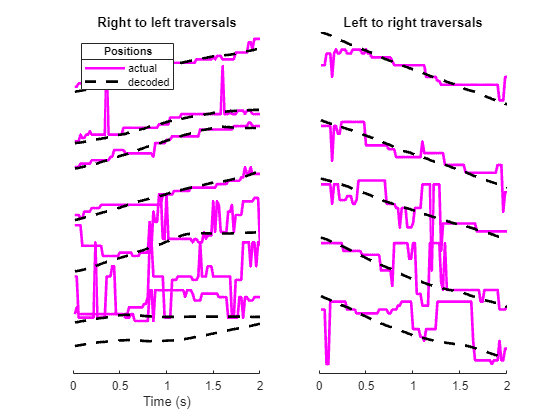

figure;
%plotting only a fraction of all indices
trialList = unique(Nav.trialID(Nav.Condition == 1 & ~isnan(Nav.trialID)));
sampleRate = 1 / mean(diff(Nav.sampleTimes));
spacing = 30;%vertical spacing between curves in unit of Xpos

%Plot actual and decoded positions
for i = 1:numel(trialList)
    idx = find(Nav.trialID == trialList(i));
    timeidx = (1:numel(idx)) / sampleRate;
    idx = idx(timeidx <= 2);
    timeidx = timeidx(timeidx <= 2);
    idir = 1 + double(nanmean(Nav.XDir(idx)) < 0);
    subplot(1,2,idir);

    decPos = Dec.XDecMax(idx);
    decPos(~isnan(decPos)) = Dec.Xbincenters(decPos(~isnan(decPos)));
    hold on;plot(timeidx, decPos + spacing*(i-1),'m','linewidth', 2);

    hold on; plot(timeidx, Nav.Xpos(idx) + spacing*(i-1),'k--','linewidth', 2);
end
subplot(1,2,1);
set(gca,'Ytick', [], 'YColor', 'none')
xlabel('Time (s)')
lgd = legend({'actual','decoded'}, 'location', 'northwest');
title(lgd,'Positions')
title('Right to left traversals')
subplot(1,2,2);
set(gca,'Ytick', [], 'YColor', 'none')
title('Left to right traversals')

Do the same for direction of travel

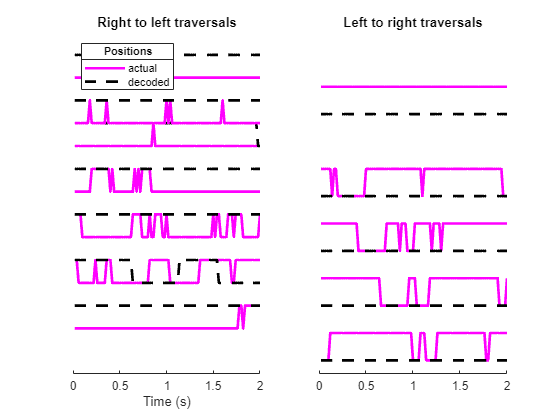

figure;
%plotting only a fraction of all indices
trialList = unique(Nav.trialID(Nav.Condition == 1 & ~isnan(Nav.trialID)));
sampleRate = 1 / mean(diff(Nav.sampleTimes));
spacing = 2;%vertical spacing between curves in unit of XDir

%Plot actual and decoded direction of travel
for i = 1:numel(trialList)
    idx = find(Nav.trialID == trialList(i));
    timeidx = (1:numel(idx)) / sampleRate;
    idx = idx(timeidx <= 2);
    timeidx = timeidx(timeidx <= 2);
    idir = 1 + double(nanmean(Nav.XDir(idx)) < 0);
    subplot(1,2,idir);

    decDir = Dec.YDecMax(idx);
    decDir(~isnan(decPos)) = Dec.Ybincenters(decDir(~isnan(decPos)));
    hold on;plot(timeidx, decDir + spacing*(i-1),'m','linewidth', 2);

    hold on; plot(timeidx, Nav.XDir(idx) + spacing*(i-1),'k--','linewidth', 2);
end
subplot(1,2,1);
set(gca,'Ytick', [], 'YColor', 'none')
xlabel('Time (s)')
lgd = legend({'actual','decoded'}, 'location', 'northwest');
title(lgd,'Positions')
title('Right to left traversals')
subplot(1,2,2);
set(gca,'Ytick', [], 'YColor', 'none')
title('Left to right traversals')

Calculate the distribution of decoded positions as a function of actual positions over the data on which the decoder has been trained.

%time indices to consider
valididx = Dec.decparams.traintidx & ~isnan(Dec.XDecMax) & ~isnan(Dec.X);

%Calculating the distribution of decoded positions as a function of the
%actual positions
Xdecmat = Compute2DMap(Dec.X(valididx), Dec.XDecMax(valididx), ones(size(Dec.X(valididx))), Dec.nXbins, Dec.nXbins);

%Smoothing the distribution across decoded position (but not across
%actual positions).
Xdecmat = GaussianSmooth(Xdecmat, [1 0]);

%Expressing the distribution as a probability density, i.e. normalizing
%so that everything sums to one for each actual position bin.
Xdecmat = Xdecmat ./ sum(Xdecmat, 1);

%Normalizing this confusion matrix by the chance level, i.e. 1 / Dec.nXbins.
Xdecmat = Xdecmat / (1/Dec.nXbins);



Plot the confusion matrix.

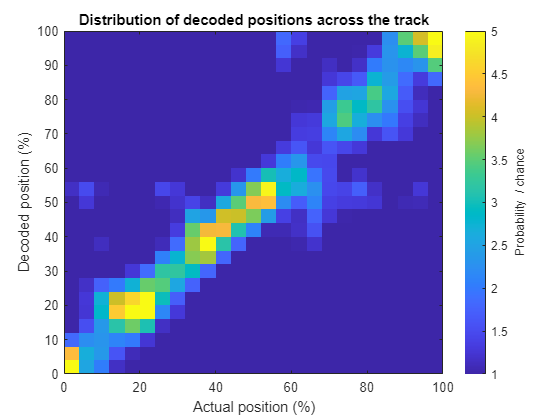

figure;
imagesc(Dec.Xbincenters, Dec.Xbincenters, Xdecmat);
set(gca,'Clim', [1 5], 'YDir', 'normal');
ylabel('Decoded position (%)')
xlabel('Actual position (%)')
title('Distribution of decoded positions across the track');
c = colorbar;
c.Label.String = 'Probability  / chance';

Calculate the distribution of decoded directions as a function of actual directions.

%time indices to consider
valididx = Dec.decparams.traintidx & ~isnan(Dec.YDecMax) & ~isnan(Dec.Y);

%Calculating the distribution of decoded directions as a function of the
%actual directions
LRdecmat = Compute2DMap(Dec.Y(valididx), Dec.YDecMax(valididx), ones(size(Dec.Y(valididx))), Dec.nYbins, Dec.nYbins);

%Smoothing the distribution across decoded directions (but not across
%actual directions).
LRdecmat = LRdecmat ./ sum(LRdecmat, 1);

%Normalizing this probability by the chance level, i.e. 1 / Dec.nYbins.
LRdecmat = LRdecmat / (1/Dec.nYbins);

Plot the confusion matrix for directions.

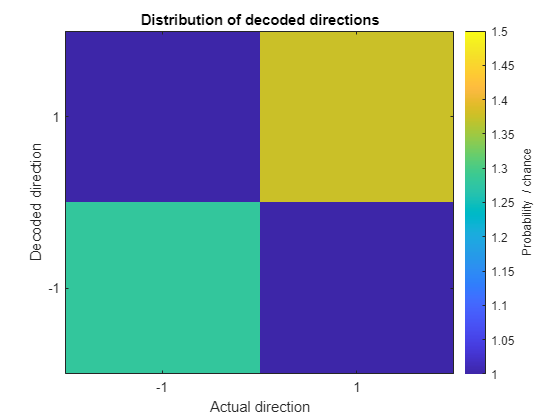

figure;
imagesc(Dec.Ybincenters, Dec.Ybincenters, LRdecmat);
set(gca,'Clim', [1 1.5], 'YDir', 'normal', 'Xtick', [-1 1], 'Ytick', [-1 1]);
ylabel('Decoded direction')
xlabel('Actual direction')
title('Distribution of decoded directions');
c = colorbar;
c.Label.String = 'Probability  / chance';